# **Group <number> - Finite Element program for 2D problems**

### Group identification

Group number: <27>

Student #1: <Rodrigo Coelho 109747>

Student #2: <Joaquim Neves 110615>

Problem type: <Fluídos>

Element type: <T3>

### Coding instructions

In this LiveScript program you will implement a simple program for a specific 2D problem with a specific type of element. This element definition should be algorithmically gerenal and hence, be defined in a local frame. This results in all quantities first being calculated in this local frame and then being transformed in the global frame. 

The code should be organized as follows:

- Initialization of parameters

- Nodes coordinates and elements are generated

- Define nodal loads and boundary conditions

- Compute for each element and assemble stiffness matrix and force vector

- Impose boundary conditions and solve the system of equations

- Post-process the solution

The functions that define the behaviour of elements are called multiple times. These should be convenientely be programmed by the group. Particularly, the following functions:

- `shape_E# `and` diff_shape_E# `compute the values of the element `E#` shape functions for local coordinates

- `stif_E# `computes the stiffness matrix for our specific element

- `stress_E# `postprocesses the solution in an element to analyse the stress field

- `int_gauss `retrieves the quadrature weights given the specification of $N_G\times N_G$ Gauss integration points (see image below)

*Note:* Triangle elements E = T; Quadrilateral elements E = Q; # is the number of nodes of the element

Besides other utility functions, here we point out the following functions:

- `cf` to apply boundary conditions

- `assemb` to assemble the global system of equations

Mesh data

For simple domains you can easily generate nodal coordinate data and connectivities with few commands. 

In the case of a more complicated domains we provide the function `read_mesh_files` to read a mesh from ANSYS files and then adapt the array structure. Note that these files are easily accessed generated in ANSYS by issuing the commands `nlist` and `elist` and then should be saved and put in the same directory of the current MATLAB file.

Acompanying code: Q9 element

Along this template, we also make available an example of an example code for 2D elasticity with Q9 elements for a simple problem. You may draw inspiration from this code and even copy most of its content, if useful. In that case try to be as surgical in your modifications as possible and should change the appropriate functions to deal with your own element and the appropriately choose the number of quadrature points. The post-processing in that code, however may be completely different and you should adapt to your own analysis and generate different types of plots (e.g. line plots, vectorial arrow plots, etc..).

## **Accountability and ethics**

**Students are expected to ALWAYS give credit to their references! For instance, if you copy a section of the Q9 code, please acknowledge it, e.g. through a code commenting.**

**The use of AI tools is ****not**** prohibitted. However, whenever it is used, it should be properly reported. In the case you use matlab autocompletion capabililties, acknowledge it. If you use an LLM please acknowledge it. Again, this can be done through code commenting, by providing the tool (e.g. ChatGPT) and the instruction/prompt given.**

**Note that all the scripts will be subjected to an AI detector, and if not acknowledged, this can affect the score of the project.**

### Begin coding here

Initilization

clear all

% Element info

elem_type = 'T3';          % element type ( e.g. 'Q9' )
nnel      = 3  ;    % number of nodes per element
ndof      = 1    ;       % number of degrees of freedom per node
vx  = 22 ; %velocidade na parede
rho = 1.2; %densidade
p1 = 0 ; % relativa  a hidrostatica local

Import mesh

% Import nodal and element information
% and form global coordinates array "gcoord"
% connectivities array "nodes"
% from NLIST and ELIST files from ANSYS
[gcoord, nodes] = read_mesh_files("NLIST_airfoil2.lis","ELIST_airfoil2.lis", nnel);

    %mesh de troubleshoot
    % gcoord = [
    %         0, 0;  3, 0; 1, 0; 2, 0;
    %         0, 1; 3, 1; 1, 1; 2, 1;
    %         0, 2; 3, 2; 1, 2; 2, 2;];
    % nodes = [
    % 1, 3, 7;  1, 7, 5;    
    % 3, 4, 8;  3, 8, 7;   
    % 4, 2, 6;  4, 6, 8;    
    % 5, 7, 11; 5, 11, 9;  
    % 7, 8, 12; 7, 12, 11;  
    % 8, 6, 10; 8, 10, 12;];  

nnode = size(gcoord,1);       % number of nodes
nelem = size(nodes, 1) ;       % number of elements

sdof  = ndof*nnode;           % total number of degrees of freedom

Plot Mesh - elements + nodes

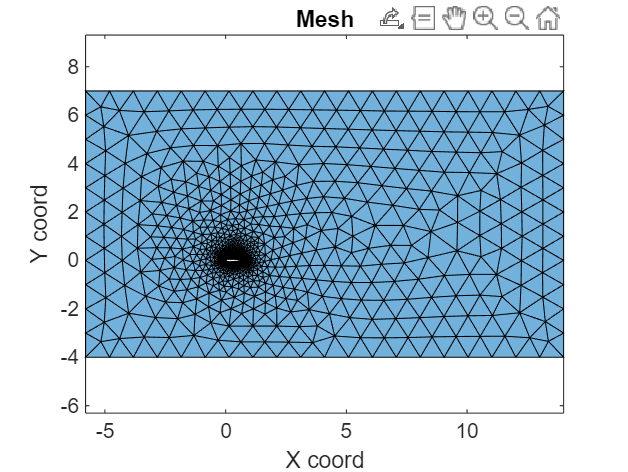

figure
hold on

drawingField(gcoord, nodes, elem_type, ones(size(gcoord,1)));
drawingMesh(gcoord, nodes, elem_type, '-');
%scatter(gcoord(:,1), gcoord(:,2), 10, 'ok', 'Filled')

colormap sky
title("Mesh")
xlabel("X coord")
ylabel("Y coord")
axis equal
box on

Global degrees of freedom numbering on global nodes

idof=0;
for i=1:nnode
    for j=1:ndof
        idof     = idof + 1;
        gdl(i,j) = idof;
    end
end

Element material and physical properties

for iel = 1:nelem
    k_const(iel) = 1;
    fhgen(iel) = 0;
end

Assign Nodal point loads

% Form point load vector
% 
P = zeros(sdof, 1);

% Loop todos os elementos para encontrar os q têm fronteira na parede
for i = 1 : nelem
    % nós do elemento
    n = nodes(i, :);
      
    % Checkar os 3 lados
    %  1: No 1 para no 2
    % 2: No 2 para no 3
    % 3: Node 3 para no 1
    
    local_edges = [1 2; 2 3; 3 1];
    
    for j = 1 : 3 %
        n1 = n(local_edges(j, 1)); %numeraçao global de no A da aresta a avaliar
        n2 = n(local_edges(j, 2)); %num global de no B da aresta a avaliar
        
        % Check se nos na entrada (x ~= -5.8)
        if gcoord(n1, 1) < -5.8+1e-4 && gcoord(n2, 1) < -5.8+1e-4
            % 1. dimensao da aresta
            dy = gcoord(n1, 2) - gcoord(n2, 2);
            dx = gcoord(n1, 1) - gcoord(n2, 1); 
            L = sqrt(dx^2 + dy^2);
            
            % 2. metade para cada lado, multiplica pela dimensao
            load_contribution = (vx * L) / 2; 
            
            % 3. somar
            P(n1) = P(n1) + load_contribution; % neg pq 
            P(n2) = P(n2) + load_contribution; 
        end
        
    end
end



Assign Essential boundary conditions

% Form arrays with constrained DoFs and the value of the constraint 
%left_wall = max(gcoord(2, :))
aux = find(gcoord(:, 1) > 13.999); % encontrar nos na parede direita
aux_n = size(aux,1);
bcdof = aux';
bcval = zeros( 1, aux_n );


Element stiffness matrix and force vector computations and respective assembling

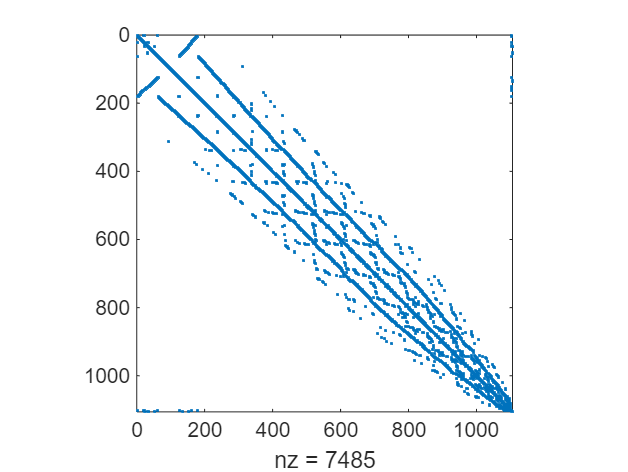

% Initialize the global arrays
ff    = zeros(sdof,     1);  % global force vector
kk    = zeros(sdof,  sdof);  % global stiffness matrix
index = zeros(nnel*ndof,1);  % index vector of the element degrees of freedom (for assembly)


% Assemble global stiffness matrix, force vectors
% Hints: 
%        - For each element construct the element arrays;
%        - Use functions eldof and assemb to "alocate" each element array
%       to the corresponding global array.
%
%
for iel = 1:nelem % - Loop over all elements;

    n         = nodes(iel,1:nnel);     % numeraçao global dos nos do elemento
    xe        = gcoord(n,1);           % coord dos nos
    ye        = gcoord(n,2);
    [ k , f ] = matriz_T3( k_const(iel) , ...
                        fhgen(  iel) , ... 
                        xe , ye      );  % cmatriz do elemento
    index   = eldof(iel,nnel,nodes,gdl);
    [kk,ff] = assemb(kk,ff,k,f,index);

end

figure
title('Matriz rigidez esqueleto')
spy(kk)



% Impose boundary conditions in the global system

[ kk , ff ] = cf( kk , ff , bcdof , bcval ); %ver agora nao esquecer!!!!!!!!!!!!!

% Impose point loads
ff=ff+P;

% Solve the system
u=kk\ff;


 Post-processing

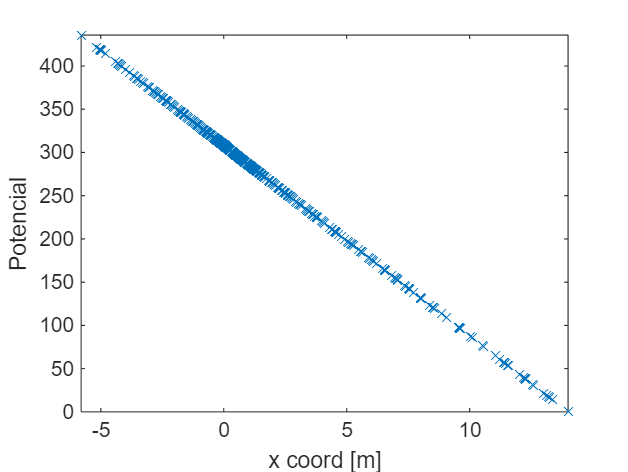

% Plot the primary variables 
% 
% potencial
figure;
x = gcoord(:,1);
plot( x , u , 'x' );
xlabel('x coord [m]')
ylabel('Potencial')
axis( [ min(x), max(x) , min(u) , max(u) ] )
axis normal

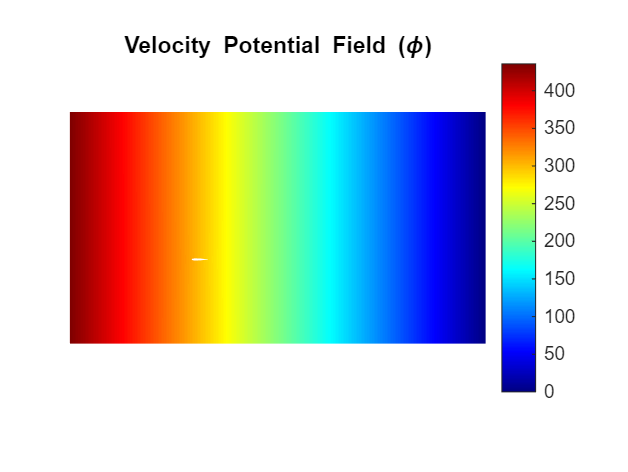

% potencial Color Map
%recurso à ferramenta Gemini #Help me plot the variables i have calculated
%using this program#
figure
% We use the original coordinates (gcoord)
drawingField(gcoord, nodes, 'T3', u); 

hold on
% Draw the mesh wireframe on top (optional, makes it easier to see elements)
%drawingMesh(gcoord, nodes, 'T3', '-'); fica muito cluttered com a mesh

axis equal
axis off
colorbar
title('Velocity Potential Field (\phi)');
colormap jet % 'turbo' or 'jet' are good for fluids

Compute and plot secondary variables (derivatives, etc...)

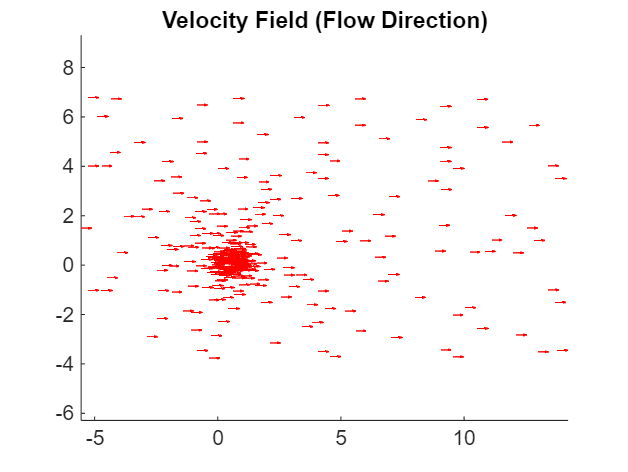

%recurso à ferramenta Gemini #Help me plot the new variables (vectors) i have calculated
%using this program
figure
title('Velocity Field (Flow Direction)');
axis equal
hold on
%drawingMesh(gcoord, nodes, 'T3', '-'); % Draw background mesh

% criar as vars
center_x = zeros(nelem, 1);
center_y = zeros(nelem, 1);
vec_vx   = zeros(nelem, 1);
vec_vy   = zeros(nelem, 1);

% velocidade no centro de cada elemento
for iel = 1:nelem
    n = nodes(iel, :);
    xe = gcoord(n, 1);
    ye = gcoord(n, 2);
    ue = u(n); % Potential at the 3 nodes
    
    % calcular gradiente no centro
    % T3,  gradiente constante no elemento
    [ksi_c, eta_c] = deal(1/3, 1/3); % centroide
    dN = diff_shape_T3(ksi_c, eta_c);
    Jacob = dN' * [xe, ye];
    dN_global = dN * inv(Jacob)'; 
    
    %  Vel = -Grad(Phi) = -dN_global' * ue
   
    vel = -dN_global' * ue;
    
    % guardar p grafico
    center_x(iel) = mean(xe);
    center_y(iel) = mean(ye);
    vec_vx(iel)   = vel(1);
    vec_vy(iel)   = vel(2);
end

% Plot 
%o apoio do gemini foi principalmente nesta secção
antidensidade = 5; %estava  aficar com demasiadas setas
adesenhar = 1 : antidensidade : nelem;


quiver(center_x(adesenhar), center_y(adesenhar), vec_vx(adesenhar), vec_vy(adesenhar), 0.50,'r', 'LineWidth', 0.3);
hold off

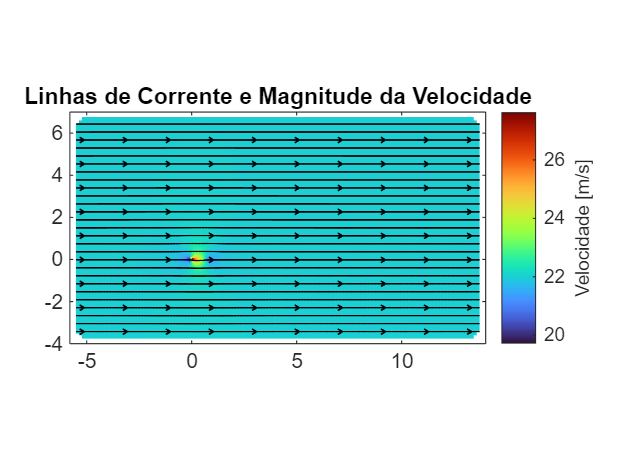



%esta secção é 100% do gemini, tentativa de fazer um grafico mais legivel
%acabou por se plotar stream lines, apesar de tudo é bom, excepto a
%distorção do dominio (há valores atribuidos dentro da asa)



% --- 1. Preparar a Grelha (Grid) ---
% Definir a resolução da grelha (quanto maior, mais suave, mas mais lento)
resolution = 140; 
x_range = linspace(min(gcoord(:,1)), max(gcoord(:,1)), resolution);
y_range = linspace(min(gcoord(:,2)), max(gcoord(:,2)), resolution);
[X_grid, Y_grid] = meshgrid(x_range, y_range);

% --- 2. Interpolar Velocidades para a Grelha ---
% Usamos os centros dos elementos (center_x, center_y) calculados no seu loop anterior
VX_grid = griddata(center_x, center_y, vec_vx, X_grid, Y_grid, 'linear');
VY_grid = griddata(center_x, center_y, vec_vy, X_grid, Y_grid, 'linear');

% Calcular a magnitude (velocidade escalar) na grelha
SPEED_grid = sqrt(VX_grid.^2 + VY_grid.^2);

% --- 3. Plotar ---
figure
title('Linhas de Corrente e Magnitude da Velocidade');
hold on

% CAMADA 1: Cores de Fundo (Magnitude da Velocidade)
% Usamos pcolor para pintar a grelha
surf_plot = pcolor(X_grid, Y_grid, SPEED_grid);
shading interp       % Deixa as cores suaves (sem ver os quadrados)
set(surf_plot, 'EdgeColor', 'none'); % Remove bordas

% CAMADA 2: Linhas de Corrente (Direção do Fluxo)
% 'streamslice' desenha automaticamente as linhas baseadas nos vetores U e V
% O número '2' no final é a densidade das linhas (aumente para mais linhas)
lines = streamslice(X_grid, Y_grid, VX_grid, VY_grid, 2);

% Ajustar a aparência das linhas (Pretas e finas)
set(lines, 'Color', 'k', 'LineWidth', 0.8); 

% --- Visuals ---
colormap turbo    % ou 'jet', 'parula'
c = colorbar;
c.Label.String = 'Velocidade [m/s]';
axis equal
axis tight
box on

% Definir limites para evitar ver áreas brancas (NaN) fora do domínio
xlim([min(gcoord(:,1)) max(gcoord(:,1))]);
ylim([min(gcoord(:,2)) max(gcoord(:,2))]);

hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Codigo 100% AI, utilizado para determinar as coordenadas do nó mais
%proximo de uma dada localização
% Target coordinates
x_target = 0.2;
y_target = 0.07;

% Calculate Euclidean distance from every node to the target
distances = sqrt((gcoord(:,1) - x_target).^2 + (gcoord(:,2) - y_target).^2);

% Find the index of the smallest distance
[min_dist, nodeID] = min(distances);

% Output the result
fprintf('Found Node ID: %d\n', nodeID);

Found Node ID: 221


fprintf('Actual Coordinates: (%f, %f)\n', gcoord(nodeID,1), gcoord(nodeID,2));

Actual Coordinates: (0.185159, 0.070263)



% Find rows (elements) where any column contains node 83
elementIDs = find(any(nodes == nodeID, 2));

% Display the result
disp('Elements containing Node 83:');

Elements containing Node 83:


disp(elementIDs);

         293
         295
         296
        1689
        1778
        1779
        1988



%%%%%%%%%%%%%%%%%%%%%%%%%%%%

el_speed = sqrt(vec_vx.^2 + vec_vy.^2); % Speed per element

disp(max(el_speed))

   28.0318



disp(min(el_speed))

    9.4189




%Aproximação da velocidade para cada nó

vel_media = 0;
n = 0;
for i = 1 : size(elementIDs)
    vel_media = vel_media + el_speed(elementIDs(i));
    n = n+1;
end

media = vel_media/n

media = 25.3247

Calculo de pressões

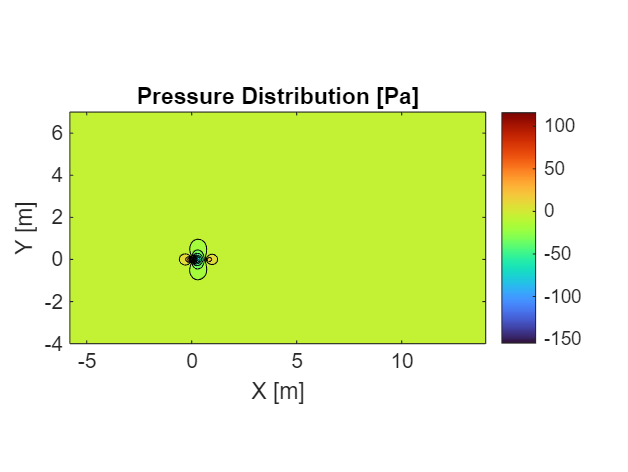





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



%%pressoes
%bernoulli -> p1+rohvquad/2 = p2+rohvquad/2
%energia na parede
v_sum = zeros(nnode, 1);
count = zeros(nnode, 1);
el_speed = sqrt(vec_vx.^2 + vec_vy.^2); % velocidade p cada elemento






for i = 1:nelem
    n = nodes(i,:);
    v_sum(n) = v_sum(n) + el_speed(i);
    count(n) = count(n) + 1;
end
v_nodes = v_sum ./ count; % Nodal Velocity Magnitude

% 3. Calculate Pressure (Bernoulli Equation)
%    P_local = P_ref + 0.5*rho*(v_ref^2 - v_local^2)
P_nodes = p1 + 0.5 * rho * (vx^2 - v_nodes.^2);


%recurso à ferramenta Gemini #Help me plot this other variable i have calculated
%using this program

% Create an Interpolation Grid
%    (Contour plots need a square grid, not triangles)
resolution = 200; % Increase this for smoother curves
x_range = linspace(min(gcoord(:,1)), max(gcoord(:,1)), resolution);
y_range = linspace(min(gcoord(:,2)), max(gcoord(:,2)), resolution);
[X_grid, Y_grid] = meshgrid(x_range, y_range);

% 5. Interpolate Data
%    'natural' looks best, but 'linear' is faster if it's slow
P_grid = griddata(gcoord(:,1), gcoord(:,2), P_nodes, X_grid, Y_grid, 'natural');

% 6. Plot
figure
% Filled Contours (20 levels)
[C, h] = contourf(X_grid, Y_grid, P_grid, 20); 

hold on
title('Pressure Distribution [Pa]');
xlabel('X [m]');
ylabel('Y [m]');
axis equal
axis tight

% Visuals
colormap turbo      % Good contrast for pressure
colorbar            % Show the scale

%clabel(C, h, 'Color', 'w', 'FontSize', 8);





### Appended functntons

Shape functions and derivatives

function N = shape_T3(ksi, eta)
% Form array with shape fucntions: N

N = [ 1 - ksi - eta ; ...
      ksi           ; ...
      eta           ];

end


function dN = diff_shape_T3(ksi, eta)
% Form array with derivatives of shape fucntions: dN

    dN = [-1, -1; 1, 0; 0, 1];

end


Gauss integration

function [ksi, eta, pesos] = int_gauss(order)
%
% Gauss points and weights
% Establish the gauss integration point coordinates and weights, for
% different order integration 
% arrays: ksi     - local coordinates
%         weights - Gauss weights


switch order
    case 1
        ksi = 1/3;
        eta = 1/3;
        pesos = 1;

    case 3
        ksi = [0.5; 0.0; 0.5];
        eta = [0.0, 0.5, 0.5];
        pesos = [1/3; 1/3; 1/3];
        
    case 4
        ksi   = [   1/3  ;  0.2  ;  0.2  ;  0.6  ];
        eta   = [   1/3  ;  0.6  ;  0.2  ;  0.2  ];
        pesos = [ -27/48 ; 25/48 ; 25/48 ; 25/48 ];
end

end

Compute element stiffness matrix

function [k, f] = matriz_T3(ke, fe, xe, ye)
% Establish the matrix of properties
%Parameters
r = 1;
n = size(xe, 1);
[ksi, eta, wp] = int_gauss(r);

% Compute element stiffness matrix
k = zeros(n,n);
f = zeros(n,1);

for p = 1 : r
    %Funcoes formas e derviadas
    N  = shape_T3( ksi(p) , eta(p) );
    dN = diff_shape_T3( ksi(p) , eta(p) );

    %Jacobiano
    Jacob = dN' * [xe , ye];
    inv_J = inv( Jacob );
    det_J = det(Jacob);

    %comeca a construir matriz pre integraçao gauss
    F_k = zeros(n,n);
    for i = 1: n
        for j = 1: n
            F_k(i,j) = ( inv_J(1,1) * dN(i,1) + inv_J(1,2) * dN(i,2) ) * ...
                       ( inv_J(1,1) * dN(j,1) + inv_J(1,2) * dN(j,2) ) ...
                       + ...
                       ( inv_J(2,1) * dN(i,1) + inv_J(2,2) * dN(i,2) ) * ...
                       ( inv_J(2,1) * dN(j,1) + inv_J(2,2) * dN(j,2) ); 
   
        end
    end 
    %acabar integração de gauss

    k = k + 0.5 * ke * F_k * det_J * wp(p);
    f = f + 0.5 * fe * N   * det_J * wp(p);

end


end


Compute elemental postprocess quantities

Apply boundary conditions

function [kk,ff]=cf(kk,ff,bcdof,bcval)
% Apply boundary conditions to the system [kk]{u}={ff}
% kk    - global stiffness matrix
% ff    - global force vector
% bcdof - vector of contrained degree of freedom
% bcval - vector with the constraint value

ff              = ff - kk(:,bcdof)*bcval'          ; % colunas cprrespondentes a vars q conhecemos passam para o lado direito
kk(bcdof,:)     = zeros(size(bcdof,2),size(kk,2))  ; % apagamos o q ja passamos para o outro lado
kk(:,bcdof)     = zeros(size(kk,1),size(bcdof,2))  ; % apagamos o q ja passamos para o outro lado
kk(bcdof,bcdof) = eye(size(bcdof,2),size(bcdof,2)) ; % forçar 1 na diagonal
ff(bcdof)       = bcval'                           ; % para aplicar cf

end



Assemble global system of equations

function [kk,ff]=assemb(kk,ff,k,f,index)
% Assemble global striffness matrix and force vector
% kk    - global stiffness matrix
% ff    - global force vector
% k     - element stiffness matrix
% f     - element force vector
% index - element list of the defrees of freedom 

ff(index)       = ff(index) + f      ;
kk(index,index) = kk(index,index) + k;

end

Utilitiy function

function index=eldof(iel,nnel,nodes,gdl)
% Extract the defress of freedom of the element iel
% reshape used so that index stays in a line vector

index=reshape(gdl(nodes(iel,:),:)',1,[]);

end


Utility functions for post proc

function drawingMesh(nodeCoordinates,elementNodes,elementType,lineType)
% drawingMesh mesh representation for 1D and 2D FEs
% Input data required
%
% nodeCoordinates : Cartesian coordinates of the nodes
% elementNodes    : Element connectivity
% elementType     : Type of element (e.g. linear, quadratic, etc.)
% lineType        : Type of line for plotting purposes
%

% resize the vector to suit 2d and 3d problems (beams)
if size(nodeCoordinates,2) == 2
    nodeCoordinates(end,3) = 0;
end

switch elementType
    case 'T3' % triang tres nos
        for k = 1:size(elementNodes,1)
            patch(nodeCoordinates(elementNodes(k,:),1), nodeCoordinates(elementNodes(k,:),2), ...
                'w', 'FaceColor', 'none', 'LineStyle', lineType, 'EdgeColor', 'k');
        end
    
    otherwise
        disp('Element type not available')
end
end




function drawingField(coord,element,tipoElemento,field)

if ( nargin == 4 )
    nodesoff=0;
end

if ( size(field) == size(element) )
    elementalField=1;
else
    elementalField=0;
end
if (size(coord,2) < 3)
    for c=size(coord,2)+1:3
        coord(:,c)=[zeros(size(coord,1),1)];
    end
end

holdState=ishold;
hold on

    if ( strcmp(tipoElemento,'T3') )
    ord = [1, 2, 3, 1];
end

for e=1:size(element,1)
    xpt=coord(element(e,ord),1);
    ypt=coord(element(e,ord),2);
    zpt=coord(element(e,ord),3);
    if ( elementalField )
        fpt=field(e,ord);
    else
        fpt=field(element(e,ord));
    end
    fill3(xpt,ypt,zpt,fpt)
end

shading interp
axis equal

if ( ~holdState )
    hold off
end
end


Function for mesh import

function [gcoord, nodes] = read_mesh_files(n_file_name, e_file_name, nnel)

    fid = fopen(n_file_name,'r');
    gcoord = [];
    while ~feof(fid)
        line = strtrim(fgetl(fid));
        if ~(~ischar(line) || isempty(line) || ~isstrprop(line(1),'digit'))
            nums = sscanf(line,'%f');
            gcoord(end+1,:) = nums(2:3).'; 
        end
    end
    fclose(fid);

    fid = fopen(e_file_name,'r');
    nodes = [];
    while ~feof(fid)
        line = strtrim(fgetl(fid));
        if ~(~ischar(line) || isempty(line) || ~isstrprop(line(1),'digit'))
            nums = sscanf(line,'%f');
            nodes(end+1,:) = nums(7:7+nnel-1).'; 
        end
    end
    fclose(fid);

end